### Initialization

N = 10^7;
qpsk_cons = [0; 1; 3; 2];
clipping_dB = 3;
SNR_dB = 20;
IFFT_length = 1024;
n_c = 400;
sfc = ceil(pow2(13) / n_c);
channel_type = 'AWGN';

carrier_bins = 76:475;
conj_carrier_bins = IFFT_length - carrier_bins + 2;

### Part a.

bits = generate_bits(N);
[r_bits, frame_num] = ofdm_block(bits, N, qpsk_cons, IFFT_length, n_c, clipping_dB, SNR_dB, sfc, carrier_bins, conj_carrier_bins, channel_type);
ber = error_calculation(r_bits, N, bits)

ber = 0.5000

frame_num

frame_num = 596

### Part b.

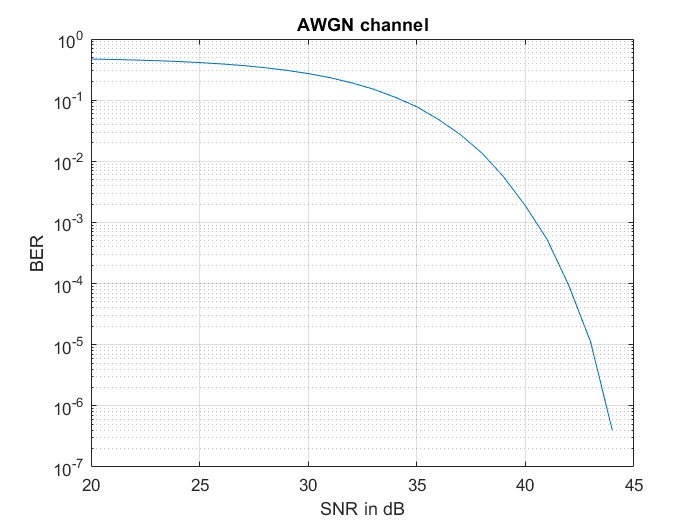

bits = generate_bits(N);
snr_dB = 20:50;
ber = zeros(length(snr_dB), 1);
for c = 1:length(snr_dB)
    [r_bits, ~] = ofdm_block(bits, N, qpsk_cons, IFFT_length, n_c, clipping_dB, snr_dB(c), sfc, carrier_bins, conj_carrier_bins, channel_type);
    ber(c, 1) = error_calculation(r_bits, N, bits);
end

figure
semilogy(snr_dB, ber)
xlabel('SNR in dB')
ylabel('BER')
grid on
title('AWGN channel')

### Part c.

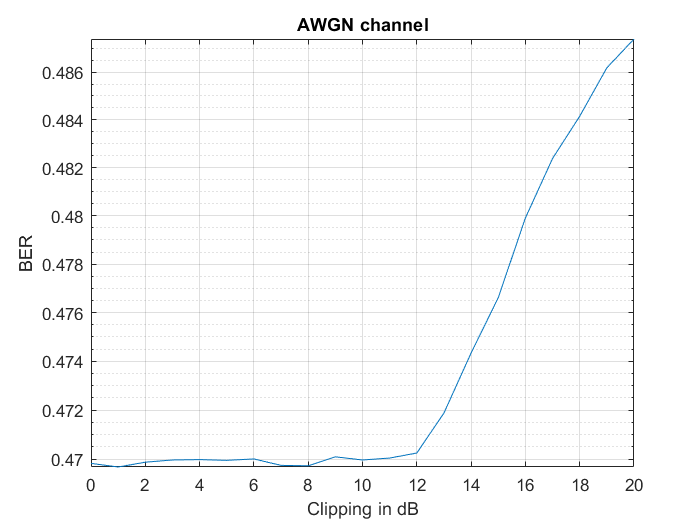

clipping_array_dB = 0:20;
bits = generate_bits(N);
ber = zeros(length(clipping_array_dB), 1);
for c = 1:length(clipping_array_dB)
    [r_bits, ~] = ofdm_block(bits, N, qpsk_cons, IFFT_length, n_c, clipping_array_dB(c), SNR_dB, sfc, carrier_bins, conj_carrier_bins, channel_type);
    ber(c, 1) = error_calculation(r_bits, N, bits);
end

figure
semilogy(clipping_array_dB, ber)
xlabel('Clipping in dB')
ylabel('BER')
title('AWGN channel')
grid on

### Part d.

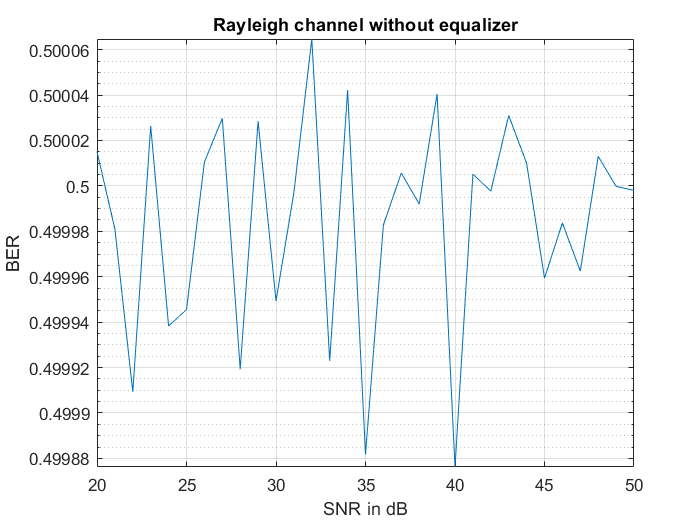

channel_type = 'Rayleigh';
alpha = raylrnd(ones(2*8*(sfc+1)*IFFT_length*(5/4) + frame_num*(sfc+1)*IFFT_length*(5/4), 1));
bits = generate_bits(N);
snr_dB = 20:50;
ber1 = zeros(length(snr_dB), 1);
for c = 1:length(snr_dB)
    [r_bits, ~] = ofdm_block(bits, N, qpsk_cons, IFFT_length, n_c, clipping_dB, snr_dB(c), sfc, carrier_bins, conj_carrier_bins, channel_type, alpha);
    ber1(c, 1) = error_calculation(r_bits, N, bits);
end

figure
semilogy(snr_dB, ber1)
xlabel('SNR in dB')
ylabel('BER')
title('Rayleigh channel without equalizer')
grid on

### Part e.

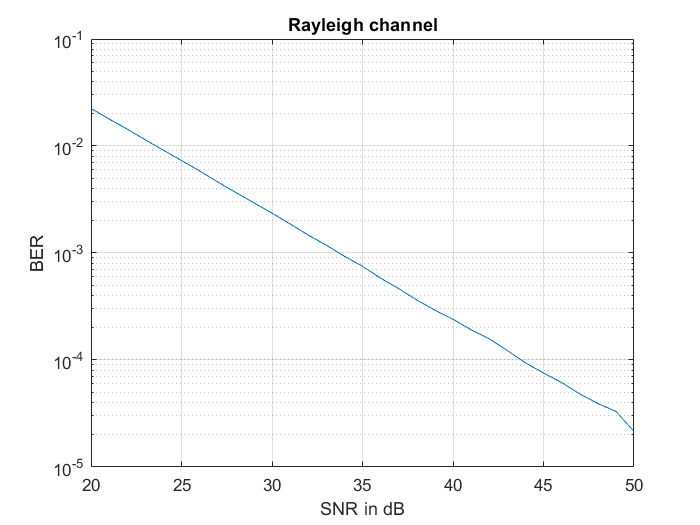

channel_type = 'Rayleigh';
bits = generate_bits(N);
snr_dB = 20:50;
ber = zeros(length(snr_dB), 1);
for c = 1:length(snr_dB)
    [r_bits, ~] = ofdm_block(bits, N, qpsk_cons, IFFT_length, n_c, clipping_dB, snr_dB(c), sfc, carrier_bins, conj_carrier_bins, channel_type, alpha);
    ber(c, 1) = error_calculation(r_bits, N, bits);
end

figure
semilogy(snr_dB, ber)
xlabel('SNR in dB')
ylabel('BER')
title('Rayleigh channel')
grid on

### Part f.

bits = generate_bits(N);
[r_bits, frame_num] = ofdm_block(bits, N, qpsk_cons, IFFT_length, n_c, clipping_dB, SNR_dB, sfc, carrier_bins, conj_carrier_bins, channel_type);

idx = 11

ber = error_calculation(r_bits, N, bits)

ber = 0.4699

## Functions

### Generate random data

function b = generate_bits(N)
b = int32(randi([0, 1], [N, 1]));
end

### QPSK modulation

function mod_sym = qpsk_modulation(N, bits, qpsk_cons)
b_r = (reshape(bits, [2, N/2])).';
b_dec = bi2de(b_r, 'left-msb') + 1;
mod_sym = qpsk_cons(b_dec);
end

### Frame divider

function framed_mod_sym = frame_dividing(mod_sym, sym_per_frame, dim3, sfc, n_c)
m = mod(length(mod_sym), sym_per_frame);
if m ~= 0
    mod_sym = [mod_sym; zeros(sym_per_frame - m, 1)];
end
framed_mod_sym = zeros(sfc + 1, n_c, dim3);
for c = 1:dim3
    framed_mod_sym(2:sfc+1, :, c) = (reshape(mod_sym((c-1)*sym_per_frame+1:c*sym_per_frame), [sfc, n_c]));
    reference_row = int32(randi([0 3], 1, n_c));
    framed_mod_sym(1, :, c) = reference_row;
end
end

### DPSK modulation

function [mod_sym, v_s] = dpsk_modulation(sym, dim3, sfc, n_c)
for c = 2:sfc+1
    sym(c, :, :) = sym(c, :, :) + sym(c - 1, :, :);
end
mod_sym = exp(1j * mod(sym, 4) * (pi / 2));
v_s = var(reshape(mod_sym, [dim3 * (sfc+1) * n_c, 1]));
end

### IFFT

function IFFT_matrix = ifft_calculator(sym, sfc, IFFT_length, dim3, carrier_bins, conj_carrier_bins)
IFFT_matrix = zeros(sfc + 1, IFFT_length, dim3);
IFFT_matrix(:, carrier_bins, :) = sym;
IFFT_matrix(:, conj_carrier_bins, :) = conj(sym);
IFFT_matrix = real(ifft(IFFT_matrix, IFFT_length, 2));
end

### CP

function t_matrix = add_cp(IFFT_matrix, IFFT_length)
col = IFFT_length/4;
t_matrix = cat(2, IFFT_matrix(:, end - col + 1:end, :), IFFT_matrix);
end

### Serial to parallel

function [t_bits, hdr_bit] = serial_to_parallel(t_matrix, sfc, IFFT_length, dim3)
hdr = reshape(de2bi(hex2dec(('1C6387FF5DA4FA325C895958DC5')'))', [], 1);
hdr_bit = repmat(hdr, fix(8*(sfc+1)*IFFT_length*5/4 / length(hdr)), 1);
hdr_bit = [hdr_bit; reshape(de2bi(hex2dec(['1C6387FF5DA4FA325C895958D']'))', [], 1)];
t_bits = [hdr_bit; reshape(t_matrix, [dim3*(sfc+1)*IFFT_length*5/4, 1]); hdr_bit];

%bonus%
t_bits = [randn(10, 1); t_bits];
end

### Clipping and Channel

function c_bits = clipping_and_channel(t_bits, SNR_dB, clipping_dB, channel_type, v_s, sfc, IFFT_length, varargin)
l = length(t_bits);
v_n = v_s / power(10, SNR_dB / 10);
noise = sqrt(v_n) * randn(l, 1);

%clipping%
M = max(t_bits);
idx = find(t_bits > M / power(10, clipping_dB / 10));
t_bits(idx) = M / power(10, clipping_dB / 10);

if strcmp(channel_type, 'Rayleigh')
    alpha = varargin{1};
    a = reshape(alpha, [sfc+1, IFFT_length*5/4, l/((sfc+1)*(IFFT_length*5/4))]);
    b = reshape(t_bits, [sfc+1, IFFT_length*5/4, l/((sfc+1)*(IFFT_length*5/4))]);
    a = a(:, IFFT_length/4+1:end, :);
    b = b(:, IFFT_length/4+1:end, :);
    t_bits = ifft(fft(a, [], 2) .* fft(b, [], 2), [], 2);
    t_bits = cat(2, t_bits(:, 3*IFFT_length/4+1:end, :) , t_bits);
    c_bits = reshape(t_bits, [l, 1]) + noise;
elseif strcmp(channel_type, 'AWGN')
    c_bits = t_bits + noise;
end
end

### Frame Detection

function [r_matrix, dim3] = frame_detection(c_bits, hdr_bit, sfc, IFFT_length)
%bonus%
[corr, lags] = xcorr(c_bits, hdr_bit);
corr = corr(lags >= 0);
[corr_max, idx] = max(corr);
if idx > length(hdr_bit) / 2
    [a, i] = maxk(corr, 5);
    i = sort(i);
    idx = i(1);
end
idx
c_bits = c_bits(idx:end, 1);

dim3 = (length(c_bits) - 2*length(hdr_bit)) / (sfc + 1) / (IFFT_length * (5/4));
r_matrix = reshape(c_bits(length(hdr_bit) + 1:end - length(hdr_bit), 1), [sfc + 1, IFFT_length * (5/4), dim3]);
end

### CP removal and FFT

function FFT_matrix = cp_removal_and_fft(r_matrix, IFFT_length)
FFT_matrix = r_matrix(:, IFFT_length/4 + 1:end, :);
FFT_matrix = fft(FFT_matrix, IFFT_length, 2);
end

### Demodulation

function r_bits = demodulation(r_mod_sym, n_c, sfc, dim3, qpsk_cons)
r_mod_sym = angle(r_mod_sym) * (180/pi);
r_mod_sym = mod(r_mod_sym, 360);
r_mod_sym = round(r_mod_sym / 90);
demod_sym = mod(diff(r_mod_sym), 4);
demod_sym = reshape(demod_sym, [dim3*sfc*n_c, 1]);
demod_sym = qpsk_cons(demod_sym + 1);
demod_sym = de2bi(demod_sym, 'left-msb');
N = numel(demod_sym);
r_bits = reshape(demod_sym.', [N, 1]);
end

### Equalizer

function eqzd_sym = eqz(sym, h, SNR_dB, dim3, IFFT_length, sfc)
h = reshape(h, [sfc+1, IFFT_length*5/4, dim3+16]);
h = h(:, IFFT_length/4 + 1:end, 9:end-8);
H = fft(h, [], 2);
eqzd_sym = sym .* (conj(H) ./ (H .* conj(H) + 1 / power(10, SNR_dB / 10)));
end

### Error Calculation

function ber = error_calculation(r_bits, N, bits)
ber = sum(r_bits(1:N, 1) ~= bits) / N;
end

### OFDM System

function [r_bits, dim3] = ofdm_block(bits, N, qpsk_cons, IFFT_length, n_c, clipping_dB, SNR_dB, sfc, carrier_bins, conj_carrier_bins, channel_type, varargin)
sym_per_frame = n_c * sfc;
mod_sym = qpsk_modulation(N, bits, qpsk_cons);
dim3 = ceil(length(mod_sym) / sym_per_frame);
framed_mod_sym = frame_dividing(mod_sym, sym_per_frame, dim3, sfc, n_c);
[mod_sym, v_s] = dpsk_modulation(framed_mod_sym, dim3, sfc, n_c);
IFFT_matrix = ifft_calculator(mod_sym, sfc, IFFT_length, dim3, carrier_bins, conj_carrier_bins);
t_matrix = add_cp(IFFT_matrix, IFFT_length);
[t_bits, hdr_bit] = serial_to_parallel(t_matrix, sfc, IFFT_length, dim3);
if strcmp(channel_type, 'Rayleigh')
    h = varargin{1};
    c_bits = clipping_and_channel(t_bits, SNR_dB, clipping_dB, channel_type, v_s, sfc, IFFT_length, h);
else
    c_bits = clipping_and_channel(t_bits, SNR_dB, clipping_dB, channel_type, v_s, sfc, IFFT_length);
end
[r_matrix, dim3] = frame_detection(c_bits, hdr_bit, sfc, IFFT_length);
FFT_matrix = cp_removal_and_fft(r_matrix, IFFT_length);
% if strcmp(channel_type, 'Rayleigh')
%     FFT_matrix = eqz(FFT_matrix, h, SNR_dB, dim3, IFFT_length, sfc);
% end
r_mod_sym = FFT_matrix(:, carrier_bins, :);
r_bits = demodulation(r_mod_sym, n_c, sfc, dim3, qpsk_cons);
end